load("CompareSimpleObsAndKalman.mat")

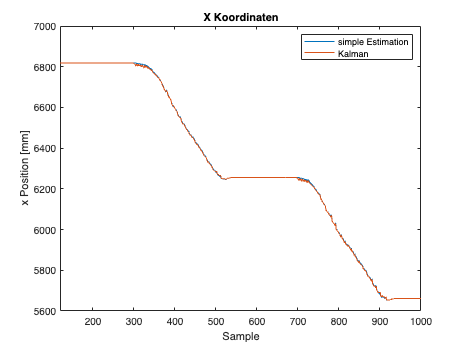


simpX = out.SimpleEst.Data(:,1);
simpY = out.SimpleEst.Data(:,2);
simpT = out.SimpleEst.Data(:,3);

KalX = out.EstPose.Data(:,1);
KalY = out.EstPose.Data(:,2);
KalT = out.EstPose.Data(:,3);

figure()
plot(simpX); hold on;
plot(KalX); hold off;
xlim([120 1000]);
title("X Koordinaten")
xlabel("Sample")
ylabel("x Position [mm]")
legend("simple Estimation", "Kalman")

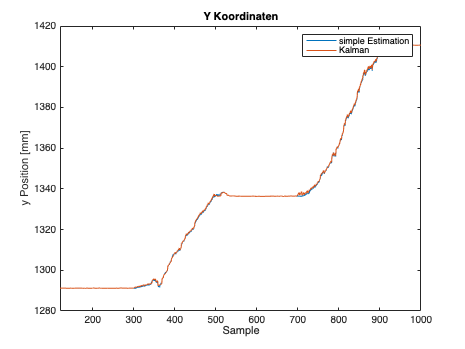



figure()
plot(simpY); hold on;
plot(KalY); hold off;
xlim([120 1000]);
title("Y Koordinaten")
xlabel("Sample")
ylabel("y Position [mm]")
legend("simple Estimation", "Kalman")

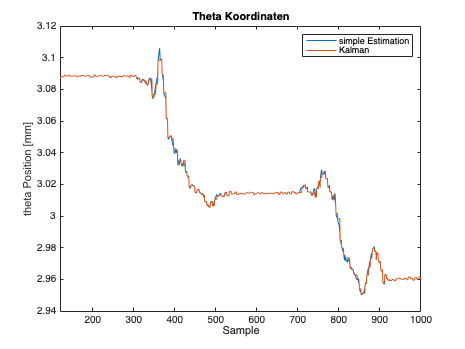


figure()
plot(simpT); hold on;
plot(KalT); hold off;
xlim([120 1000]);
title("Theta Koordinaten")
xlabel("Sample")
ylabel("theta Position [mm]")
legend("simple Estimation", "Kalman")